%% ── Fill in these parameters ──────────────────────────────────────────────
geom.wing_span    = 1.2;   % [m]   full wing span
geom.wing_AR      = 4;   % [-]   wing aspect ratio
geom.htail_span   = 0.4;   % [m]   full horizontal tail span
geom.htail_AR     = 3;   % [-]   horizontal tail aspect ratio
geom.vtail_height = 0.25;   % [m]   vertical tail height
geom.vtail_AR     = 2;   % [-]   vertical tail aspect ratio
geom.tail_arm     = 0.85;   % [m]   AC-to-AC tail moment arm
geom.nose_x       = 0.25;   % [m]   motor+prop x-position from wing LE (negative = forward)
geom.n_ducks      = 3;   % [-]   number of duck payloads
geom.n_pucks      = 1;   % [-]   number of puck payloads

geom.nose_x = -1 * geom.nose_x;
mass = defineMassConfig(geom);


=== Mass Breakdown ===
  Component             m (kg)    x (m)    z (m)
  ------------------------------------------------
  Wing                   0.730   +0.135  +0.0000
  Htail                  0.072   +0.952  +0.0000
  Vtail                  0.042   +0.948  +0.0000
  Tail spar              0.183   +0.446  +0.0000
  Fuselage               0.430   +0.025  +0.0000
  Motor+Prop             0.390   -0.250  -0.0250
  Nosecone               0.152   -0.210  +0.0000
  Battery                0.690   -0.150  -0.0250
  Receiver               0.024   -0.100  +0.0000
  Servo bat.             0.045   -0.120  +0.0000
  Gyro                   0.021   -0.130  +0.0000
  Main gear              0.125   +0.120  -0.0250
  Front gear             0.105   -0.125  -0.0250
  3 Duck(s)              0.348   +0.191  +0.0000
  1 Puck(s)              0.190   +0.084  +0.0000
  ------------------------------------------------
  TOTAL / CG             3.547  +0.0394  -0.0092

  CG: 0.0394 m = 13.1% MAC
  Ixx = 0.089

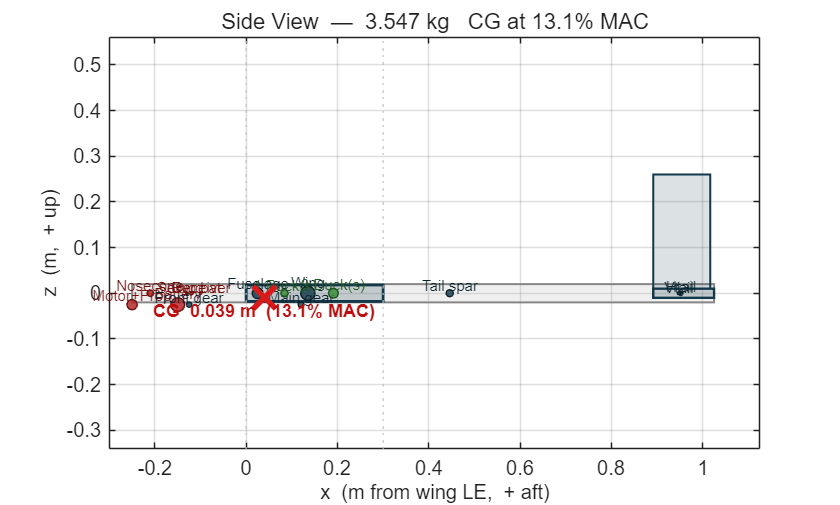

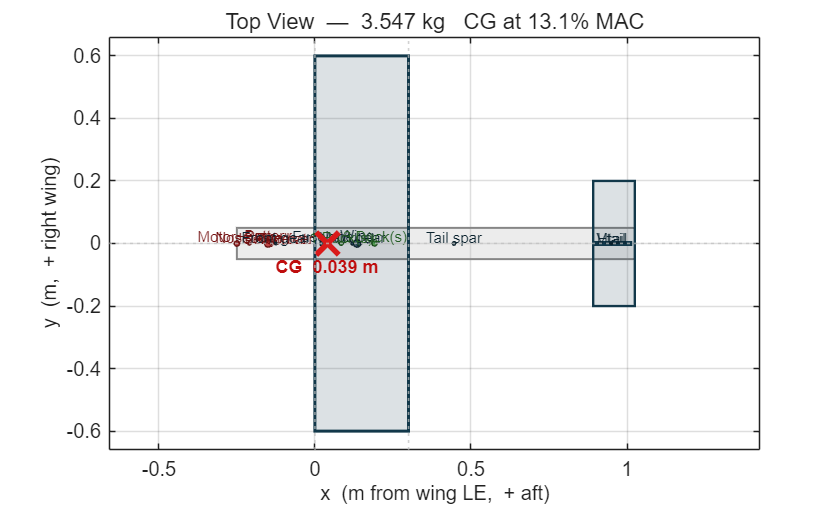

 
plotMassLayout(mass);

V = 27;
aircraft = massToAVL(mass);         % AVL-ready struct


=== Aircraft Config ===
  Wing:    span = 1.200 m   chord = 0.3000 m   AR = 4.00   S = 0.3600 m²
  Htail:   span = 0.400 m   chord = 0.1333 m   x_le = 0.8917 m
  Vtail:   h    = 0.250 m   chord = 0.1250 m   x_le = 0.8917 m
  Tail arm = 0.8500 m   Vht = 0.420   Vvt = 0.061
  Mass     = 3.547 kg
  CG       = 0.0394 m (13.1% MAC)


out      = runAVL(aircraft, V);     % run AVL

Flight condition:
  V         = 27.00 m/s
  rho       = 1.2250 kg/m3
  mass      = 3.547 kg
  CL_cruise = 0.2164
AVL geometry file written: C:\Users\kaspe\OneDrive\Cornell\All\Coding\end-of-semester-25-26\src\avl\dfo.avl
Open in AVL with:  load C:\Users\kaspe\OneDrive\Cornell\All\Coding\end-of-semester-25-26\src\avl\dfo.avl
Then view with:    oper -> g
Mass file written: C:\Users\kaspe\OneDrive\Cornell\All\Coding\end-of-semester-25-26\src\avl\dfo.mass
Running AVL...
Done. Output files:
  Stability: C:\Users\kaspe\OneDrive\Cornell\All\Coding\end-of-semester-25-26\src\avl\dfo_stability.txt
  AVL log:   C:\Users\kaspe\OneDrive\Cornell\All\Coding\end-of-semester-25-26\src\avl\avl_log.txt


avl      = parseAVLOutput(out.stability_file);


=== AVL Results ===
  Trim alpha     = -1.027 deg
  Trim elevator  = +2.215 deg
  CL             =  0.2164
  CDi (Trefftz)  =  0.00392  [induced only -- CD0 from sizing script]
  Span eff. e    =  NaN
  Neutral pt Xnp =  0.1098 m

  --- Pitch ---
  CLa  = +3.7965 /rad
  Cma  = -0.0003 /rad   (< 0 = stable)
  Cmq  = -7.1424 /rad

  --- Lateral/Directional ---
  Clb  = -0.0279 /rad
  Cnb  = +0.1426 /rad   (> 0 = weathercock stable)
  Clp  = -0.3511 /rad   (roll damping)
  Cnr  = -0.2110 /rad   (yaw  damping)
  Spiral ratio   =  0.405  (> 1 = spirally stable)


modes    = computeAVLModes(avl, aircraft, V);


=== Flight Dynamics Modes ===
  Phugoid         σ = -0.0065   (non-oscillatory)   [stable]
  Short Period    σ = -4.3748   (non-oscillatory)   [stable]
  Dutch Roll      σ = -1.1622   ω = +7.9751 rad/s   [stable]
  Roll            σ = -485.6009   (non-oscillatory)   [stable]
  Spiral          σ = +0.0626   (non-oscillatory)   t2 = 11.07 s  [UNSTABLE]


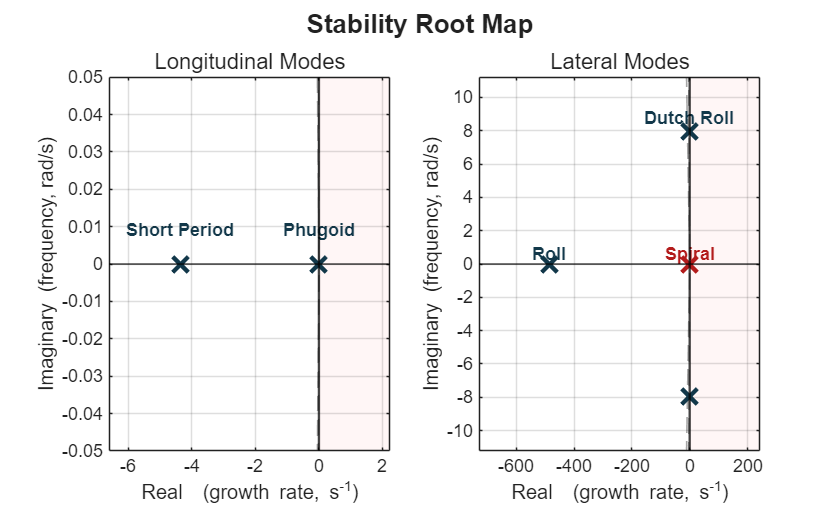

Mode: Spiral          t2 = 11.074 s


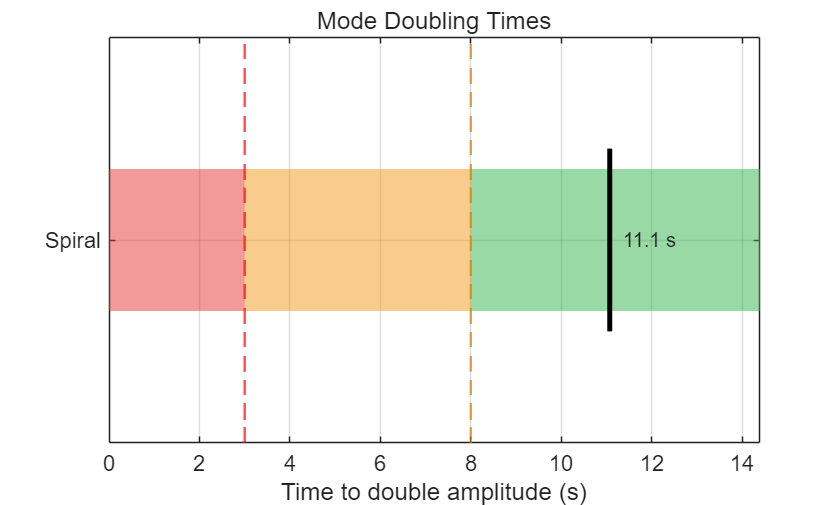


plotAVLStability(modes);